# Transition from 1D to 2D

clear all, close all, clc
set_defaults()

## Dimension independent syntax

One benefit of the operator implementation is that it hides the details of the coordinate system and spatial dimensions similar to the dyadic notation (div, grad, curl). Consider the instantaneous problem for a steady confined aquifer in both 1D and 2D:

PDE:        $-\nabla\cdot\left[K\nabla h\right]=q_p$     on   $x \in \left[0,\,1\right]\quad\times\quad y \in \left[0, 1\right]$

BC:         $\left.\mathbf{q}\cdot\hat{\mathbf{n}}_i\right|_{x=0} = 1$   and     $h(x,y=1) = 0$.

The answer to this somewhat boring problem is simply: $h\left(x\right)=1-x$. 

This problem can be solved as a 1D or a 2D problems and we'll use it here to illustrate the differences between 1D and 2D implementations.

One of the main aims of the operator implementation is to hide the dimensionality and coordinate system in the same way that the dyadic notation hides these details. Therefore, nothing will change on the highest layer of your code - as demonstrated in the example below.

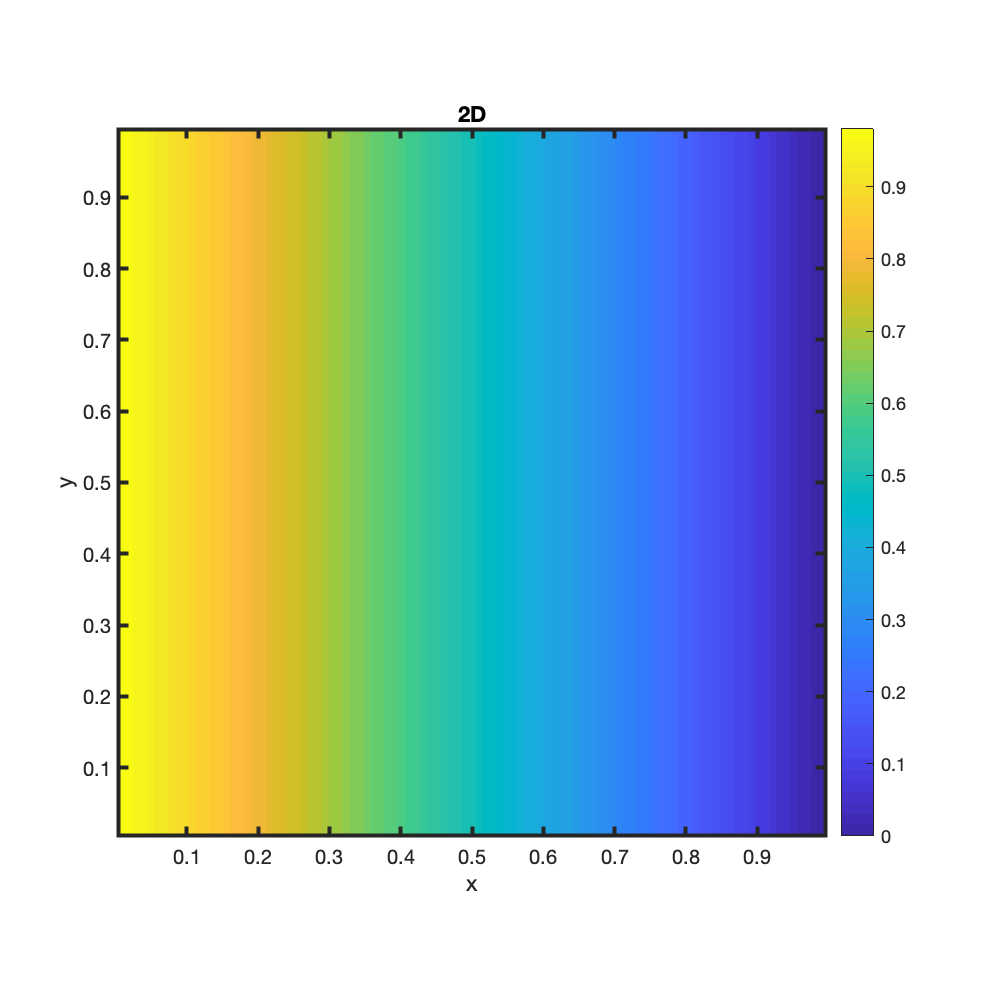

% Define the grid and operators
clear Grid
Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = 100;
Grid.ymin = 0; Grid.ymax = 1; Grid.Ny = 100;  % The only line that changes
Grid.geom = 'cartesian';
Grid = build_grid(Grid);
[D,G,I] = build_ops(Grid);
L = -D*G; fs = spalloc(Grid.N,1,0);
M = Grid.dx/2*abs(G);    % mean operator
if Grid.dx ~= Grid.dy; error('dx~=dy: need to update M!\n'); end

% Define the boundary conditions
BC.dof_dir   = [Grid.dof_xmax];
BC.dof_f_dir = [Grid.dof_f_xmax];
BC.g         = [zeros(Grid.Ny,1)];
BC.dof_neu   = [Grid.dof_xmin];
BC.dof_f_neu = [Grid.dof_f_xmin];
BC.qb        = ones(Grid.Ny,1);
[B,N,fn] = build_bnd(BC,Grid,I);

% Solve for temperature
u = solve_lbvp(L,fs+fn,B,BC.g,N);

figure('position',[10 10 500 500])
% Plot solution (o.k., the plotting changes as well)
if Grid.Ny == 1
    plot(Grid.xc,u,'-')
    xlabel 'x', ylabel 'T'
else
    [X,Y] = meshgrid(Grid.xc,Grid.yc);
    [C,h] = contourf(X,Y,reshape(u,Grid.Ny,Grid.Nx),100); colorbar
    set(h,'LineColor','none')
    xlabel 'x', ylabel 'y', title '2D'
    axis equal
end

## Changes to main functions

Of course, the changes required to go from 1D to 2D are just hidden in the functions that have been called. The following functions you have written must be updated:

- `build_grid()`: need to add all the information about the 2D grid - substantial change (trivial)

- `build_ops()`: implement 2D operators - substantial change (not trivial: Lectures 16, 17)

- `comp_mean()`: need to update averaging to 2D

The following functions that do **not** need to be changed:

- `build_bnd()`

- `solve_lbvp()`

- `comp_flux()`

These functions don't change, because the BC's are implemented as an elimination of constraints, which is independent of dimension. Benefit of the slightly more abstract approach.

## Life is more interesting in 2D

Even the simple steady confined aquifer problem can be made more interesing in 2D with some heterogeneity. In general, the hydraulic conductivity is a function of x, so that


$$-\nabla\cdot\left[K(\mathbf{x})\nabla h\right] = 0$$


Here we generate a simple Gaussian conductivity field 

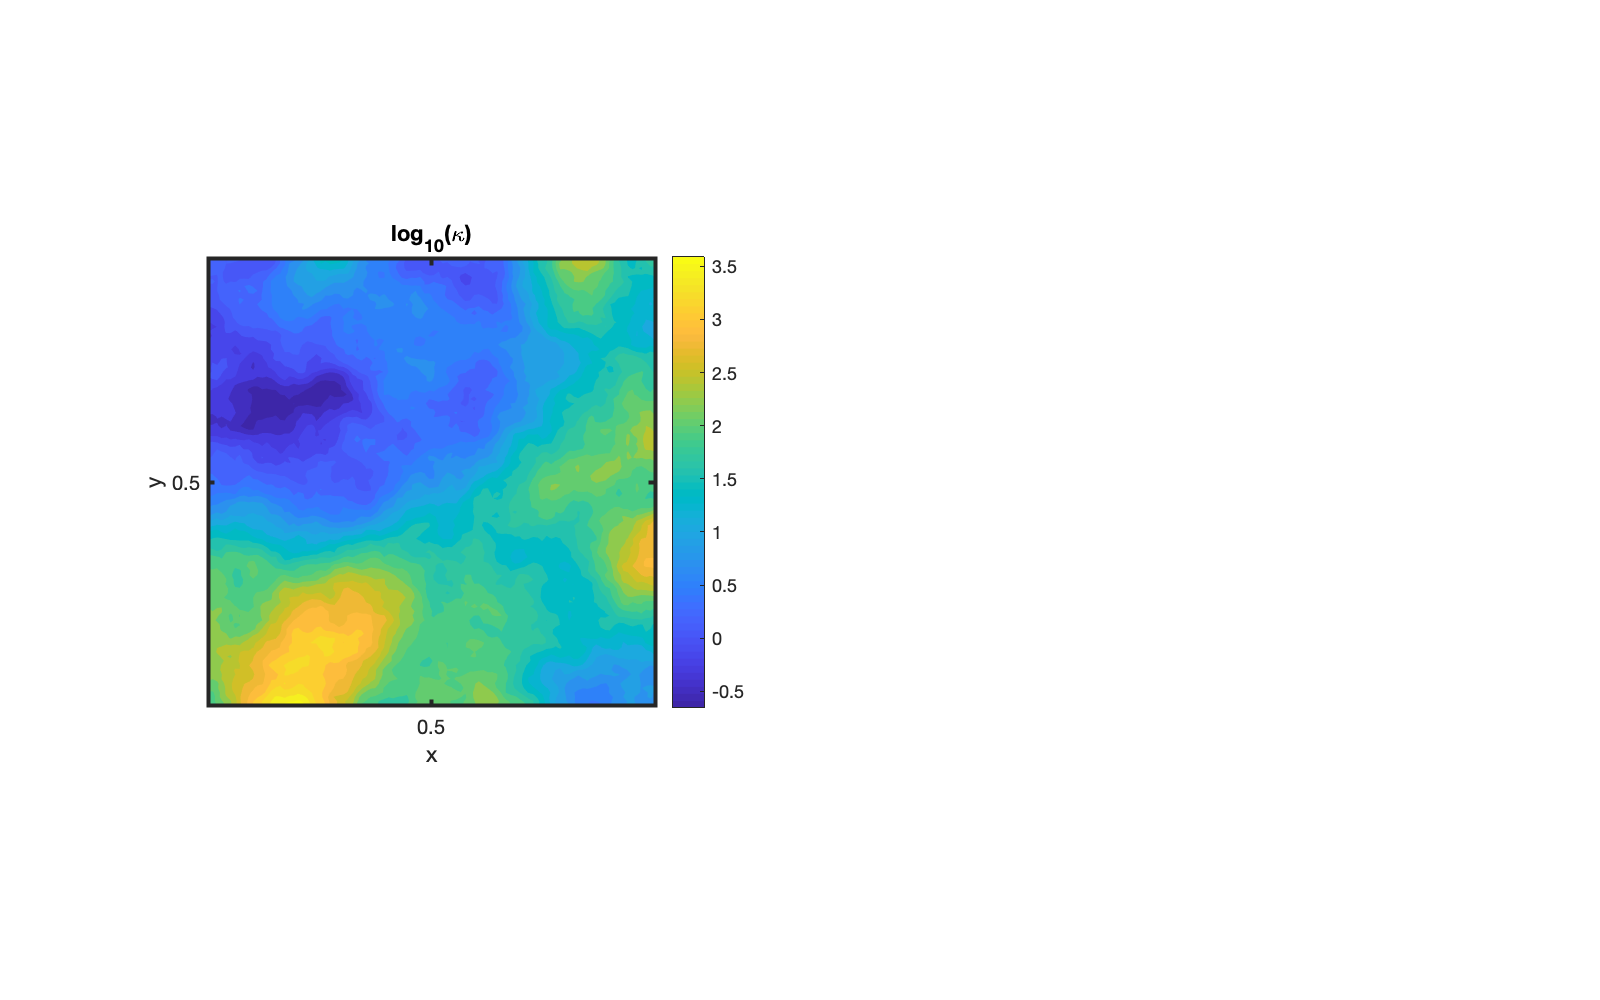

seed = 2061976;
sigma = 0.3;
rho = 1;
[logK,gamma,delta] = comp_matern(sigma,rho,Grid,D,G,I,seed);                   
logK = reshape(logK,Grid.Ny,Grid.Nx);

figure('position',[10 10 800 500])
subplot 121
[C,h2] = contourf(X,Y,logK,25); colorbar
set(h2,'LineColor','none')
set(gca,'xtick',[0 .5 1],'ytick',[0 .5 1])
xlabel 'x', ylabel 'y', title 'log_{10}(\kappa)'
axis equal

Then we can solve for the 2D head variation with the same  boundary conditions as before. The head will preferentially drop in areas of low conductivity and be almost constant in region of high conductivity.

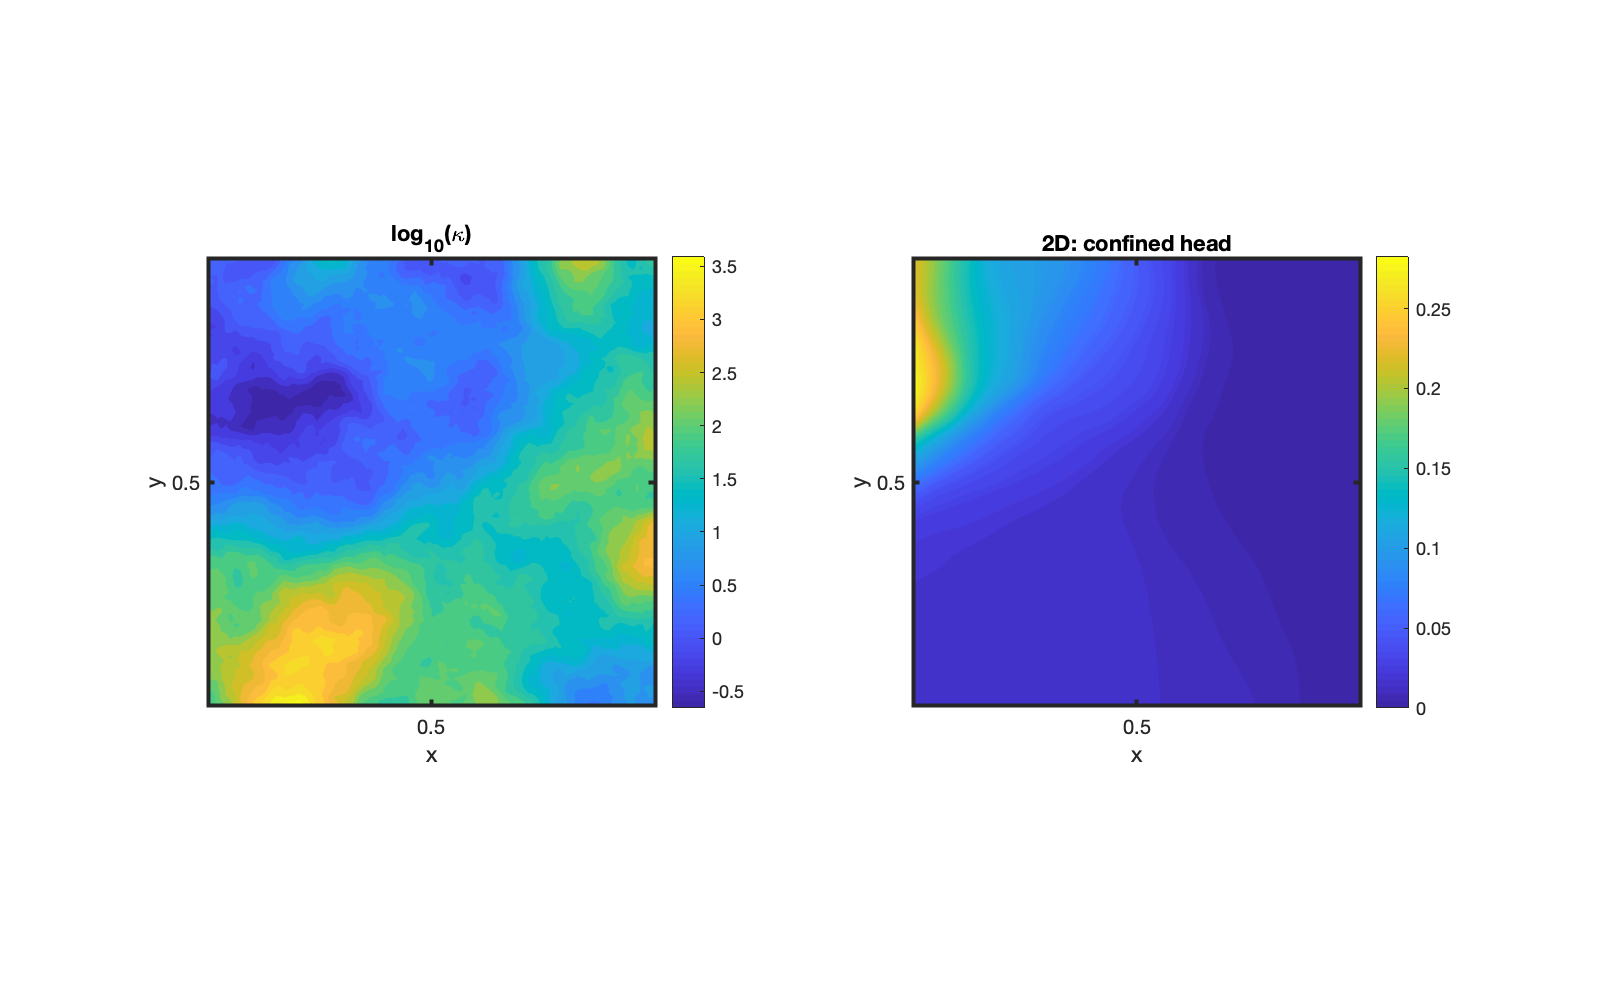

K = 10.^(logK);
Kd = comp_mean(K,-1,1,Grid);
L = -D*Kd*G;

% Solve for Head
u = solve_lbvp(L,fs+fn,B,BC.g,N);
subplot 122
[C,h3] = contourf(X,Y,reshape(u,Grid.Ny,Grid.Nx),100); colorbar
set(h3,'LineColor','none')
set(gca,'xtick',[0 .5 1],'ytick',[0 .5 1])
axis equal
xlabel 'x', ylabel 'y', title '2D: confined head'

Again this was achieved with minimal changes to the code, we simply had to add the Kd matrix into the linear operator, `L = -D*Kd*G`.

## Steady unconfined aquifers in 2D

Similarly we can solve for a steady two-dimensional heterogeneous unconfined aquifer. The governing equation is 

PDE:        $-\nabla\cdot\left[\frac{K(\mathbf{x}) h^{n+1}}{n+1}\nabla h\right]=q_p$     on   $x \in \left[0,\,1\right]\quad\times\quad y \in \left[0, 1\right]$

BC:         $\left.\mathbf{q}\cdot\hat{\mathbf{n}}_i\right|_{x=0} = 1$   and     $h(x,y=1) = 0$.

The only thing that needs to be changed in the residual and Jacobian is to add the `Kd` matrix. Also potentially switch the number of cells from `Grid.Nx` to `Grid.N` and the number of faces from `Grid.Nx+1` to `Grid.Nf`. Also the tolerance may have to be adjusted. The norm of the residual does grow with the length of the vector. Tylically we require that the residual is reduced by 6 orders of magnitude.

n_exp = 0;
Pi = 0;
[res,Jac] = steady_dupuit_res_jac(Grid,D,G,M,Kd,fs,fn,n_exp);
%% Newton iteration
tol = 1e-6; % convergence tolerance
kmax = 25;  % maximum number of iterations

% Initial guess
hD = u;     % use the confined head as initial condition
nres = norm(res(hD)); ndhD = 1; k = 0;
fprintf('Newton-Raphson iteration:\n')

Newton-Raphson iteration:


while (nres > tol || ndhD > tol) && k < kmax
    dhD = solve_lbvp(Jac(hD),-res(hD),B,BC.g,N);
    hD = hD + dhD;
    nres = norm(N'*res(hD)); ndhD = norm(N'*dhD);
    k = k+1;
    fprintf('it = %d: nres = %3.2e  ndhD = %3.2e\n',k,nres,ndhD)
    if k == 1; ndhD = 0; end % to allow exit on first iteration
end

it = 1: nres = 1.39e+07  ndhD = 9.79e+01
it = 2: nres = 3.48e+06  ndhD = 4.76e+01
it = 3: nres = 8.71e+05  ndhD = 2.19e+01
it = 4: nres = 2.18e+05  ndhD = 9.03e+00
it = 5: nres = 5.44e+04  ndhD = 3.18e+00
it = 6: nres = 1.36e+04  ndhD = 1.03e+00
it = 7: nres = 3.35e+03  ndhD = 2.95e-01
it = 8: nres = 7.24e+02  ndhD = 7.00e-02
it = 9: nres = 7.65e+01  ndhD = 1.15e-02
it = 10: nres = 9.29e-01  ndhD = 8.04e-04
it = 11: nres = 1.38e-04  ndhD = 7.67e-06
it = 12: nres = 3.03e-09  ndhD = 1.07e-09


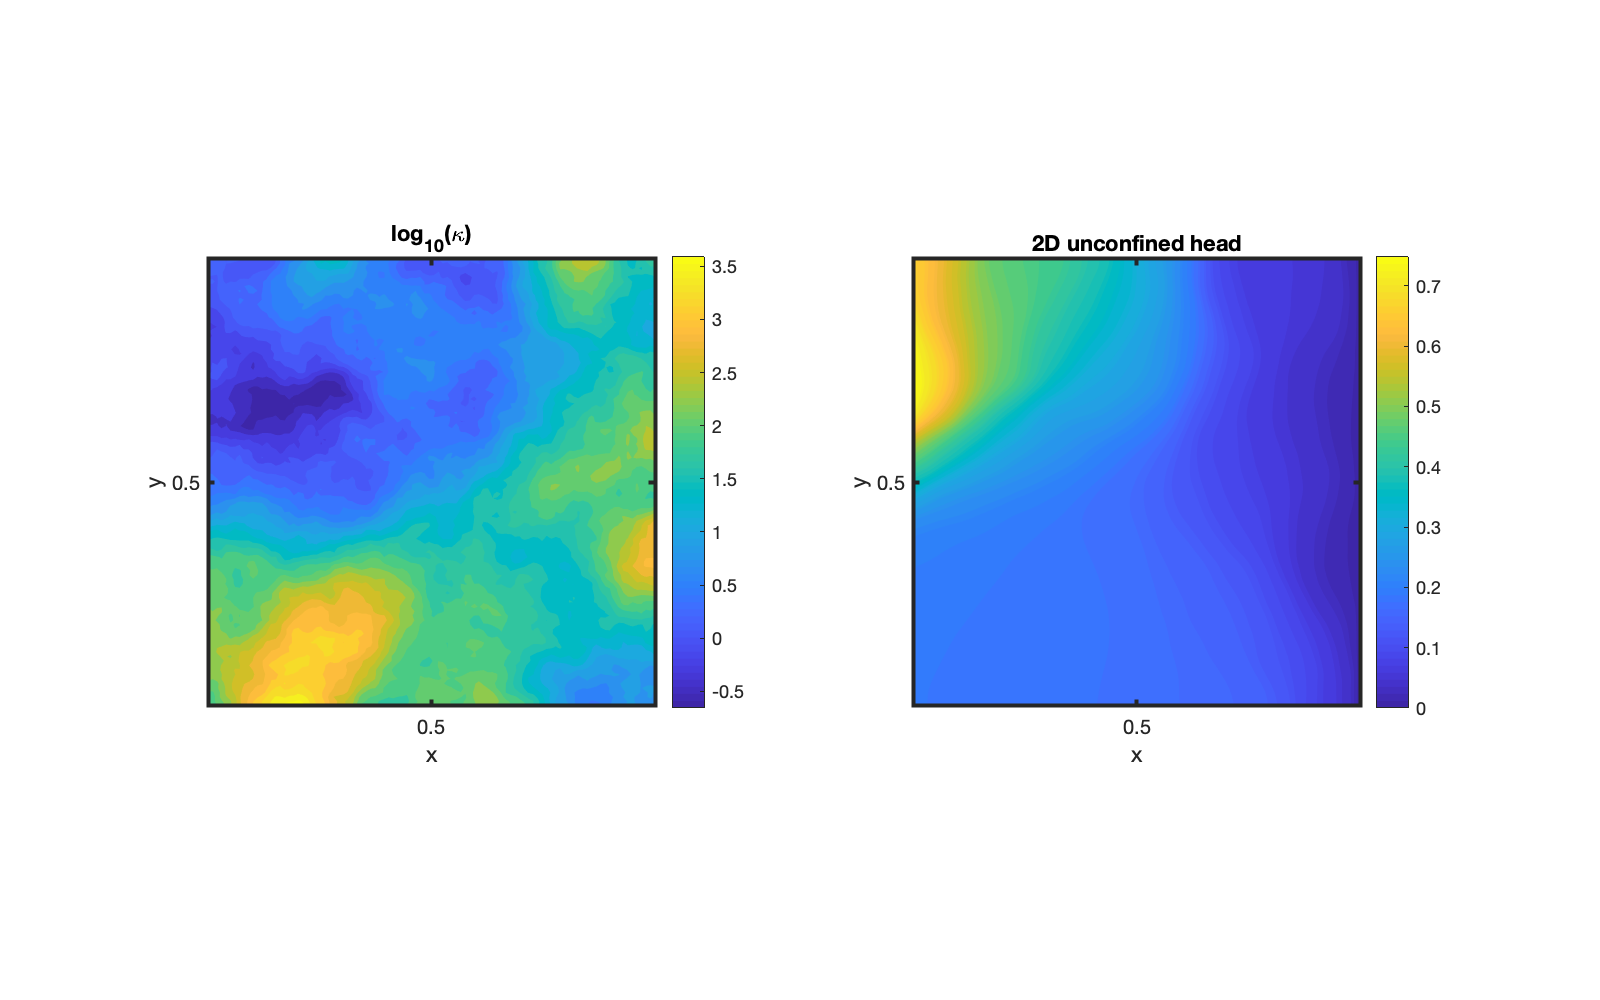


[C,h3] = contourf(X,Y,reshape(hD,Grid.Ny,Grid.Nx),100); colorbar
set(h3,'LineColor','none')
set(gca,'xtick',[0 .5 1],'ytick',[0 .5 1])
axis equal
xlabel 'x', ylabel 'y', title '2D unconfined head'

% surf(X,Y,reshape(hD,Grid.Ny,Grid.Nx))
% pbaspect([2 1 .3])
% zlim([0 2])

# Auxillary functions

## set_defaults()

function [] = set_defaults()
set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end

### steady_dupuit_res_jac()

function [res,Jac] = steady_dupuit_res_jac(Grid,D,G,M,Kd,fs,fn,n_exp)
% Function in flux term
f  = @(u) u.^(n_exp+1)/(n_exp+1);
df = @(u) u.^n_exp;

F  = @(u) spdiags(M*f(u),0,Grid.Nf,Grid.Nf);
dF = @(u) spdiags(df(u),0,Grid.N,Grid.N);

% Other 'function matrices'
GU = @(u) spdiags(G*u,0,Grid.Nf,Grid.Nf);

% Residual and Jacobian
res = @(u) D*(Kd*F(u)*G*u) + fs + fn;
Jac = @(u) D*(Kd*(GU(u)*M*dF(u) + F(u)*G));
end